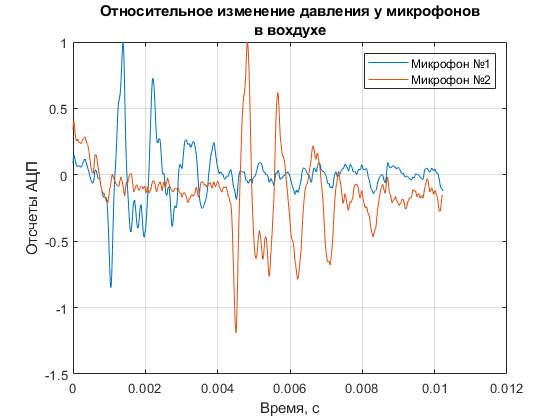

close all;
clear variables;

air0 = importdata('air.txt');
airRaw = air0.data;
breath0 = importdata("breath.txt");
breathRaw = breath0.data;
tt0 = importdata("totalTime.txt");


windowSize = 5;
b = (1 / windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
del = tt0.data / (size(airFiltered, 1) - 1) ; 
tt = 0 : del : tt0.data;

cAir = polyfit(tt', airFiltered(:, 1), 3);
cBreath = polyfit(tt', breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, tt');
airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, tt');
breathNorm = breath ./ max(breath);

del = tt0.data / (size(airNorm, 1) - 1) ; 
time = 0 : del : tt0.data;

plot(tt', airNorm(:, 1), tt', airNorm(:, 2));
grid on;
title({'Относительное изменение давления у микрофонов', 'в вохдухе'});
xlabel('Время, с');
ylabel('Отсчеты АЦП');
legend('Микрофон №1', 'Микрофон №2');

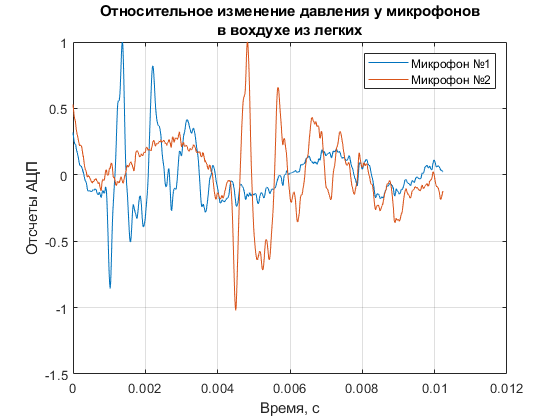


plot(tt', breathNorm(:, 1), tt', breathNorm(:, 2));
grid on;
title({'Относительное изменение давления у микрофонов', 'в вохдухе из легких'});
xlabel('Время, с');
ylabel('Отсчеты АЦП');
legend('Микрофон №1', 'Микрофон №2');


%% данные из таблицы в методичке
Ma = 28.97;%%мю смеси газов
Mw = 18.01;%% мю воды
Mco2 = 44.01;%% мю со2
Cpa = 1.0036; %%Ср
Cpw = 1.863;
Cpco2 = 0.838;
Cva = 0.7166;%% С ню
Cvw = 1.403;
Cvco2 = 0.649;
Xw = importdata('volumeFractionWater.txt');%% кол-во в-ва
T = importdata('temperature.txt'); %% температура в цельсиях
R = 8314; %% газовая постоянная
S = 1.158; %% расстояние между микрофонами
Xco2 = 0.03;
Xa = 1 - Xco2 - Xw.data;

M = Ma*Xa + Mw*Xw.data + Mco2*Xco2;%% мю
G = (Ma*Xa*Cpa + Mw*Xw.data*Cpw + Mco2*Xco2*Cpco2) / (Ma*Xa*Cva + Mw*Xw.data*Cvw + Mco2*Xco2*Cvco2); %%гамма

Speed1 = sqrt(G * R * (T.data + 273) / M); %% по формуле из методички
dt1 = S / Speed1;
disp(Speed1);

  342.3332



speed0 = 4.6232e+03